clc;clear all;close all;
%step(GCL,40);hold on
z0=rand(6,1)

z0 =     0.0782
    0.4427
    0.1067
    0.9619
    0.0046
    0.7749


syms x [3 1]
syms u [2 1]
syms t
A=jacobian(pend(t,x,u),x);
B=jacobian(pend(t,x,u),u);
xd=[zeros(3,1)];ud=[zeros(2,1)];
A=double(subs(A,[x;u],[xd;ud]))

A =      0     1     0
    -1    -1     0
     0     0     1


B=double(subs(B,[x;u],[xd;ud]))

B =      0     0
     1     1
     0     1



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


zopt =     4.5594
    1.3964
    3.2008
    0.3929
  -16.2165
    4.8282


Jopt = 14.8846

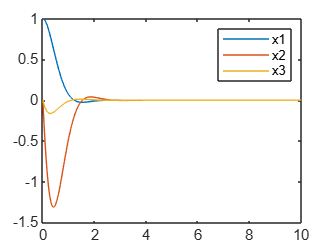

for i=4:4
    [zopt,Jopt]=fmincon(@(z)costo(z,i),z0,[],[],[],[],[],[],@(z)restr(z,A,B))
    x0=[1;0;0];
    [T,X]=ode45(@(t,x)pend(t,x,control(t,x,zopt)),[0 10],x0);
    plot(T,X(:,1));hold on;
    plot(T,X(:,2));
    plot(T,X(:,3));
    legend('x1','x2','x3')
end

function J=costo(z,i)
    fun=@(t,x)pend(t,x,control(t,x,z));
    Ts=0.01;
    T=(0:Ts:4)';Y=[];xk=[1;0;0];
    U=[];
    for k=1:length(T);
        U=[U;control(k*Ts,xk,z)];
        k1=fun(k*Ts,xk);
        k2=fun(k*Ts+Ts/2,xk+k1*Ts/2);
        k3=fun(k*Ts+Ts/2,xk+k2*Ts/2);
        k4=fun(k*Ts+Ts,xk+k3*Ts);
        xk=xk+Ts*(k1+2*k2+2*k3+k4)/6;
        Y=[Y,[1 0 0;0 0 1]*xk];
    end
    Yref=[0;0];
    if(i==1)
        J=sum(abs(Y-Yref))+0.01*sum((U.^2));
    elseif(i==2)
        J=sum(abs(Y-Yref).*T)+0.01*sum((U.^2));
    elseif(i==3)
        J=sum((Y-Yref).^2)+0.01*sum((U.^2));
    elseif(i==4)
        J=sum(sum((Y-Yref).^2)'.*T)+0.01*sum((U.^2));
    end
end

function [c,c_eq]=restr(z,A,B)
    K=reshape(z,[2 3]);
    c=[max(real(eig(A-B*K)))+0.2];%%
    c_eq=[];
end
function u=control(t,x,z)
    K=reshape(z,[2 3]);%nu nx
    u=-K*x;
end

function dx=pend(t,x,u)
    dx=[x(2);-sin(x(1))-x(2)+u(1)+u(2);x(3)+u(2)];
end